load HCVEgyptData.mat
disp(HCV)

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

class(HCV)

ans = 'table'

size(HCV)

ans =         1385          29


sum(sum(ismissing(HCV)))

ans = 0

HCV_array=table2array(HCV);

# Check for outliers

rmoutliers(HCV_array)

ans =           33           1          30           2           2           1           2           1           2           2        3178     4127797          12      180182         127         128          98          44          67          54         108          29      718359      664957      462214      456054      688986          15           4
          35           1          26           2           2           1           2           1           2           2        8093     4144255          14      217810          95          75          73          93          43          90         127          38     1121894       95572           5           5           5          14           1
          52           1          28           2           2           1           2           1           2           2       11065     4002769          15      148857         128         128         100          71          51          66         120          26      262262      595314      20


% Without considering categorical data
[cdata,tf]=rmoutliers(HCV_array(:,[1,3,11:end]))

cdata =           46          29       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085           4           2
          49          33        6490     4794631          10      146457          43          64         109          80          88          48          77          33     1041941      449939      585688      744463      582301          10           3
          58          22       11785     3882456          15      131228          66         104         121          96          65          73         114          29     1157452     1086852           5           5           5           4           4
          42          26       11620     4747333          12      177261          78          57         113         118         107          84          80          28      325694     1034008      275095      214566      635157     

tf = 1385×1 logical array
   1
   0
   1
   0
   1
   0
   0
   0
   0
   0


for i=1:1385
    if tf(i)==1
        HCV_array(i,:)=[];
    end
end
cdatat=array2table(cdata,'VariableNames',HCV.Properties.VariableNames([1,3,11:end]))

cdatat = 1381×21 table
    Age    BMI     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ___    _____    __________    ___    __________    ____    ____    ____    _____    _____    _____    _____    ___

HCV_array

HCV_array =           46           1          29           1           2           2           1           2           2           1       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085           4           2
          57           1          33           2           2           2           2           1           1           1        4178     4621191          12      151522         113          49          95         107         116           5           5           5      571148      661346           5      735945      558829           4           4
          59           1          32           1           1           2           1           2           2           2        3661     4606375          11      187684          99         104          67          48         120          94          90          30      660410      738756  

% Cross-verify with histograms and boxplots
for z=1:19
    figure
    histogram2(cdata(:,z),cdata(:,end))
end

for z=1:19
    figure
    histogram(cdata(:,z),'Normalization',"pdf")
    ylabel(cdatat.Properties.VariableNames(z))
end

for z=1:19
    figure
    histfit(cdata(:,z))
    ylabel(cdatat.Properties.VariableNames(z))
end

for z=1:19
    figure
    boxplot(cdata(:,z),cdata(:,end))
    xlabel('Stage of liver fibrosis')
    ylabel(HCV.Properties.VariableNames(z))
end

# Basic Statistical Values

% Stage and Continuous variables
sv=zeros(21,7);
for i=1:21
    sv(i,1)=min(cdatat.(i));
    sv(i,2)=max(cdatat.(i));
    sv(i,3)=range(cdatat.(i));
    sv(i,4)=mean(cdatat.(i));
    sv(i,5)=median(cdatat.(i));
    sv(i,6)=std(cdatat.(i));
    sv(i,7)=corr(cdatat.(i),cdatat.(21));
end
array2table(sv,'RowNames',cdatat.Properties.VariableNames,"VariableNames",{'Minimum','Maximum','Range','Mean','Median','Std.Dev.','Correlation'})

ans = 21×7 table
                    Minimum       Maximum        Range          Mean         Median       Std.Dev.     Correlation
                   __________    __________    __________    __________    __________    __________    ___________

    Age                    32            61            29        46.305            46        8.7717     -0.017586 
    BMI                    22            35            13        28.594            29        4.0731     -0.058403 
    WBC                  2991         12101          9110        7538.8          7514        2668.5      0.017791 
    RBC            3.8164e+06    5.0185e+06     1.202e+06    4.4223e+06    4.4385e+06    3.4657e+05  

% Stages and Categorical variables 
cadat=HCV_array(:,[2,4:10,29]);
cs=zeros(16,5);
for j=1:8
    cs(2*j-1,1)=sum(cadat(:,j)==1 & cadat(:,9)==1); % Stage 1
    cs(2*j-1,2)=sum(cadat(:,j)==1 & cadat(:,9)==2); % Stage 2
    cs(2*j-1,3)=sum(cadat(:,j)==1 & cadat(:,9)==3); % Stage 3
    cs(2*j-1,4)=sum(cadat(:,j)==1 & cadat(:,9)==4); % Stage 4
    cs(2*j-1,5)=sum(cadat(:,j)==1); % Total  
    cs(2*j,1)=sum(cadat(:,j)==2 & cadat(:,9)==1); % Stage 1
    cs(2*j,2)=sum(cadat(:,j)==2 & cadat(:,9)==2); % Stage 2
    cs(2*j,3)=sum(cadat(:,j)==2 & cadat(:,9)==3); % Stage 3
    cs(2*j,4)=sum(cadat(:,j)==2 & cadat(:,9)==4); % Stage 4
    cs(2*j,5)=sum(cadat(:,j)==2); % Total  
end
array2table(cs,'RowNames',{'Male','Female','Fever Absent','Fever Present','NausaeVomiting Absent',...
    'NausaeVomiting Present','Headache Absent','Headache Present','Diarrhea Absent','Diarrhea Present',...
    'Fatigue Absent','Fatigue Present','Jaundice Absent', 'Jaundice Present','GastricPain Absent', ...
    'Gastric Pain Present'},'VariableNames',{'Stage 1','Stage 2','Stage 3','Stage 4','Total'})

ans = 16×5 table
                              Stage 1    Stage 2    Stage 3    Stage 4    Total
                              _______    _______    _______    _______    _____

    Male                        172        181        162        190       705 
    Female                      164        149        192        171       676 
    Fever Absent                157        159        166        186       668 
    Fever Present               179        171        188        175       713 
    NausaeVomiting Absent       180        171        165        170       686 
    NausaeVomiting Present      156        159        189        191       695 
    Headache Absent             167        168       

%Data normalization
HCV_arr=normalize(HCV_array,'range');
dat=array2table(HCV_arr,'VariableNames',HCV.Properties.VariableNames)

dat = 1381×29 table
      Age       Gender      BMI       Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain      WBC         RBC       HGB      Plat       AST1       ALT1       ALT4       ALT12      ALT24       ALT36      ALT48     ALTafter24w    RNABase       RNA4       RNA12       RNAEOT      RNAEF      BaselinehistologicalGrading    Baselinehistologicalstaging
    ________    ______    ________

# Correlation

array2table(corr(HCV_arr),'Rownames',dat.Properties.VariableNames,'VariableNames',dat.Properties.VariableNames)

ans = 29×29 table
                                      Age          Gender         BMI          Fever       NauseaVomting     Headache      Diarrhea     Fatiguegeneralizedboneache     Jaundice     Epigastricpain       WBC            RBC           HGB           Plat          AST1          ALT1         ALT4         ALT12          ALT24         ALT36         ALT48       ALTafter24w     RNABase         RNA4           RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging

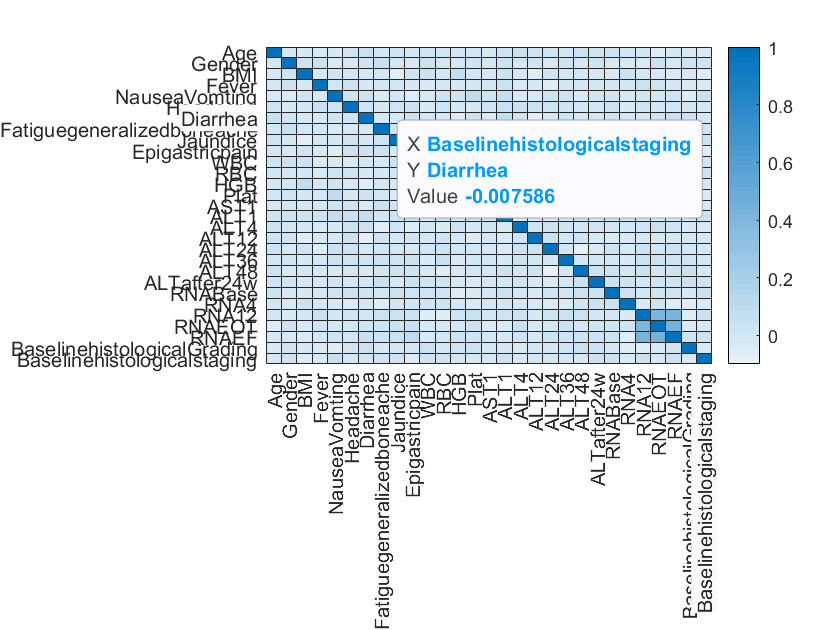

heatmap(corr(dat.Variables,'rows','complete'),'XDisplayLabels',string(dat.Properties.VariableNames),'YDisplayLabels',string(dat.Properties.VariableNames));

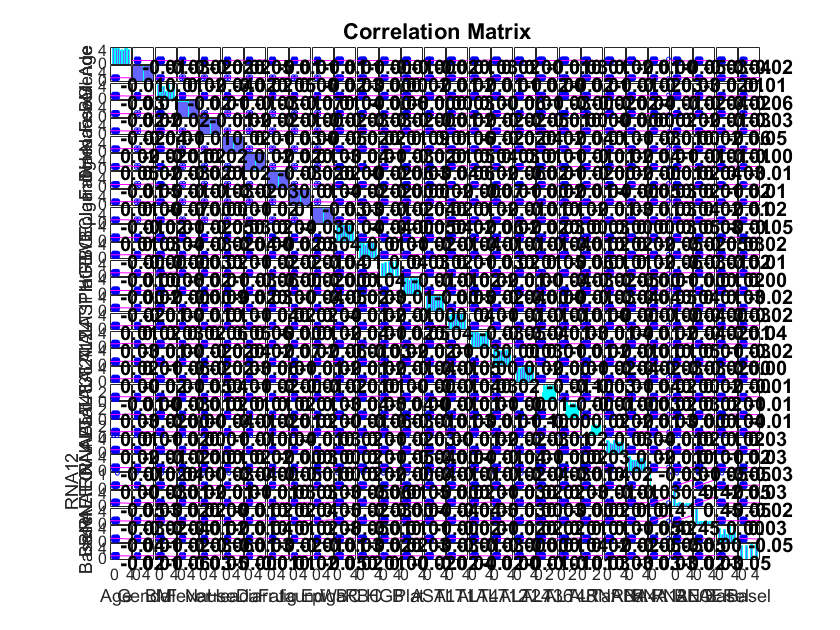

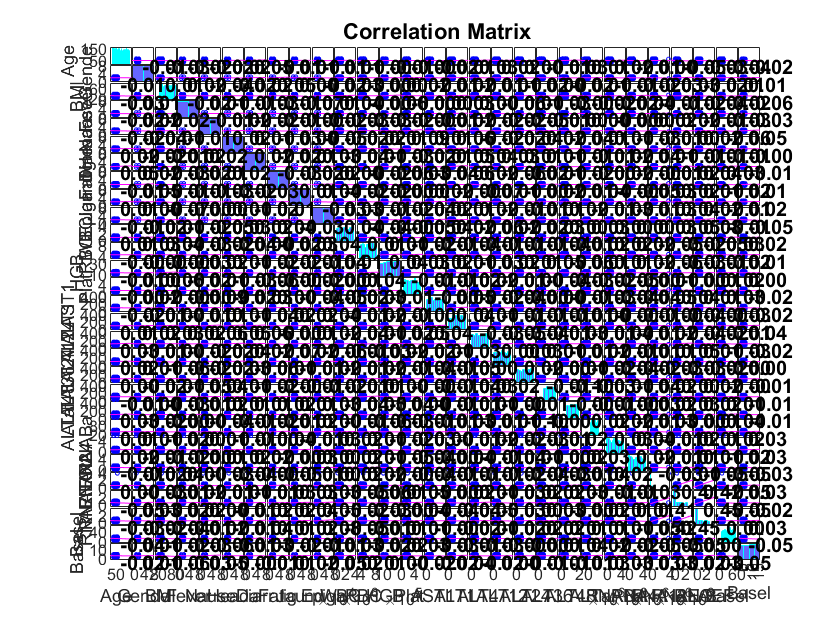

% Correlation matrix
% Takes longer to execute

%corrplot(dat)

for i=1:27
    [R1, pvalue1(i,1)]=corr(dat.(i),dat.(29));
    pvalue2(i,1)=anova1(dat.(i),dat.(29),'off');
    [R3, pvalue3(i,1)]=corr(dat.(i),dat.(29),'type','Spearman');
end

% Boneferroni and Benjamin Hochberg method
p_corrected1=27*pvalue1;
fdr1=mafdr(pvalue1);
p_corrected2=27*pvalue2;
fdr2=mafdr(pvalue2);
p_corrected3=27*pvalue3;
fdr3=mafdr(pvalue3);
table(pvalue1,p_corrected1,fdr1,pvalue2,p_corrected2,fdr2,pvalue3,p_corrected3,fdr3,'Rownames',dat.Properties.VariableNames(1:27),'VariableNames',{'Pearson_Pval','Pearson_Qval','Pearson_FDR','Anova_Pval','Anova_Qval','Anova_FDR','Spearman_Pval','Spearman_Qval','Spearman_FDR'})

ans = 27×9 table
                                  Pearson_Pval    Pearson_Qval    Pearson_FDR    Anova_Pval    Anova_Qval    Anova_FDR    Spearman_Pval    Spearman_Qval    Spearman_FDR
                                  ____________    ____________    ___________    __________    __________    _________    _____________    _____________    ____________

    Age                              0.49214         13.288         0.45258        0.34477       9.3088             1        0.48853           13.19          0.57387   
    Gender                           0.70948         19.156         0.42409        0.10103       2.7279       0.66314        0.72081   

# Unsupervised

PCA can be used for mixed data type as long as categorical variables can be reduced to binary variables without loss of data. Variables should also be normalized before using.

% PCA without normalization
X=HCV_arr(:,1:end-2)

X =     0.4828         0    0.5385         0    1.0000    1.0000         0    1.0000    1.0000         0    1.0000    0.5100         0    0.2724    0.5843    0.9438    0.6292    0.4045    0.8315    0.4228    0.9593    0.9750    0.0338    0.4482    0.1707    0.4166    0.0384
    0.8621         0    0.8462    1.0000    1.0000    1.0000    1.0000         0         0         0    0.1303    0.6695    0.4000    0.4384    0.8315    0.1124    0.6292    0.7640    0.8652         0         0         0    0.4755    0.5503         0    0.9103    0.6896
    0.9310         0    0.7692         0         0    1.0000         0    1.0000    1.0000    1.0000    0.0735    0.6572    0.2000    0.7094    0.6742    0.7303    0.3146    0.1011    0.9101    0.7236    0.6911    0.6250    0.5498    0.6147    1.0000    0.4193    0.2997
    0.8966    1.0000         0    1.0000    1.0000    1.0000         0    1.0000    1.0000         0    0.9653    0.0549    1.0000    0.2864    0.3034    0.7303    0.9213    0.6404   

stage=HCV_arr(:,29)

stage =     0.3333
    1.0000
         0
    1.0000
    0.6667
    0.3333
    0.3333
    0.3333
         0
         0


[coeff,score,latent,~,explained]=pca(X);
explained

explained =     7.8728
    7.6349
    7.3168
    7.2822
    7.1734
    6.9769
    6.7102
    6.4450
    4.4477
    3.3991


b=bar(explained)

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [0 0.4470 0.7410]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27]
        YData: [7.8728 7.6349 7.3168 7.2822 7.1734 6.9769 6.7102 6.4450 4.4477 3.3991 2.9204 2.6990 2.6407 2.6087 2.5094 2.4840 2.4116 2.3982 2.3494 2.2584 2.1950 2.1192 1.6427 1.2741 1.2410 0.8659 0.1234]

  Show all properties


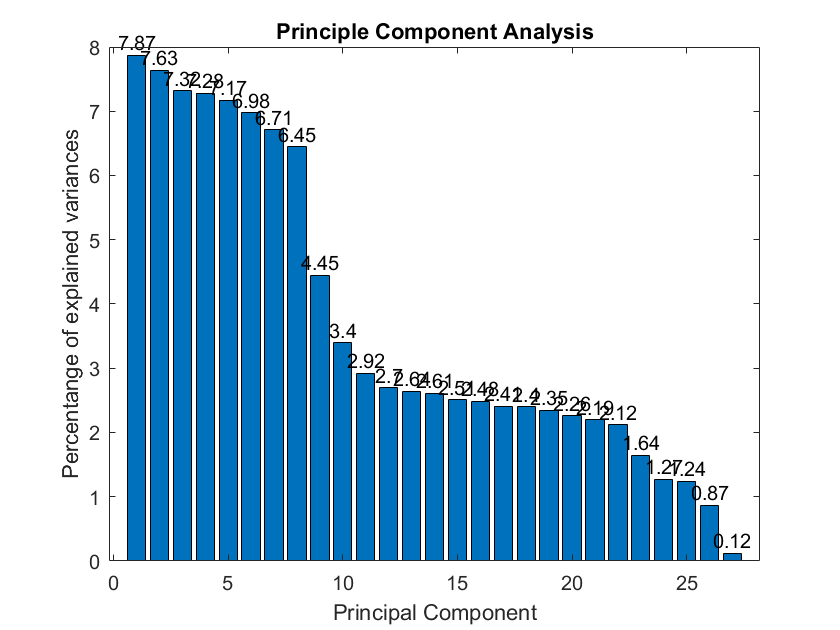

xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(round(b.YData,2));
text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
xlabel('Principal Component')
ylabel('Percentange of explained variances')
title('Principle Component Analysis')

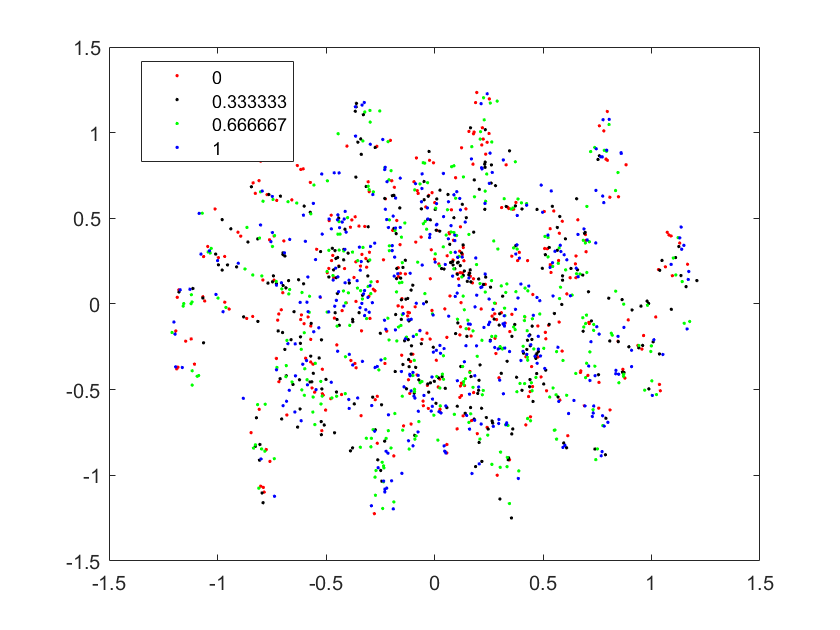

gscatter(score(:,1),score(:,2),stage,'rkgb')

Consider 0.05 as the variance threshold

features=HCV.Properties.VariableNames(1:end-2)';
PC1=abs(coeff(:,1));
sortrows(table(features,PC1),'PC1','descend')

ans = 27×2 table
               features                 PC1   
    ______________________________    ________

    {'NauseaVomting'             }      0.5587
    {'Fatiguegeneralizedboneache'}     0.55619
    {'Gender'                    }     0.42012
    {'Epigastricpain'            }     0.33121
    {'Headache'                  }     0.25554
    {'Diarrhea'                  }     0.12154
    {'ALT4'                      }    0.051366
    {'Plat'                      }    0.040148
    {'RNAEOT'                    }    0.038214
    {'Jaundice'                  }    0.035217
    {'ALT1'                      }    0.028753
    {'WBC'                       }    0.028405
    {'ALT24'                     }    0.027996
    {'RBC'                       }    0.027831
    {'ALT12'                     }    0.023729
    {'Fever'                     }    0.019822


PC2=abs(coeff(:,2));
sortrows(table(features,PC2),'PC2','descend')

ans = 27×2 table
               features                 PC2   
    ______________________________    ________

    {'Epigastricpain'            }     0.67329
    {'Diarrhea'                  }     0.43486
    {'Headache'                  }     0.37184
    {'Gender'                    }     0.29032
    {'Jaundice'                  }     0.25194
    {'Fever'                     }      0.2106
    {'NauseaVomting'             }     0.11214
    {'RNAEF'                     }    0.082696
    {'Fatiguegeneralizedboneache'}    0.043748
    {'RNAEOT'                    }    0.038597
    {'HGB'                       }    0.035639
    {'ALT1'                      }    0.029961
    {'Plat'                      }    0.028119
    {'Age'                       }    0.020355
    {'RNABase'                   }    0.016503
    {'RBC'                       }    0.016031


PC3=abs(coeff(:,3));
sortrows(table(features,PC3),'PC3','descend')

ans = 27×2 table
               features                 PC3   
    ______________________________    ________

    {'Fever'                     }     0.65921
    {'Gender'                    }     0.45424
    {'Headache'                  }     0.43757
    {'Diarrhea'                  }     0.37506
    {'Epigastricpain'            }    0.092522
    {'HGB'                       }    0.062919
    {'Fatiguegeneralizedboneache'}    0.058957
    {'ALT1'                      }    0.057055
    {'ALT24'                     }    0.038654
    {'NauseaVomting'             }    0.035657
    {'RNAEOT'                    }    0.028556
    {'WBC'                       }    0.027106
    {'BMI'                       }    0.024459
    {'AST1'                      }    0.023647
    {'RNA4'                      }    0.022816
    {'ALT12'                     }    0.021578


PC4=abs(coeff(:,4));
sortrows(table(features,PC4),'PC4','descend')

ans = 27×2 table
               features                 PC4   
    ______________________________    ________

    {'Diarrhea'                  }      0.5267
    {'Jaundice'                  }     0.48609
    {'Headache'                  }     0.46056
    {'Gender'                    }      0.3342
    {'Fever'                     }     0.25717
    {'Fatiguegeneralizedboneache'}     0.20823
    {'Epigastricpain'            }     0.20624
    {'Plat'                      }     0.05522
    {'AST1'                      }    0.036226
    {'BMI'                       }    0.035082
    {'ALT12'                     }    0.034255
    {'NauseaVomting'             }    0.030338
    {'RNA4'                      }    0.024099
    {'RNAEF'                     }    0.019128
    {'RNAEOT'                    }    0.018718
    {'WBC'                       }    0.017758


%K-means Clustering for continuous variables
k_values=2:5;
n=length(k_values);
s_score=zeros(n,1);
for i=1:n
    idx=kmeans(HCV_arr(:,[1,3,11:end-2]),k_values(i));
    s=silhouette(HCV_arr(:,[1,3,11:end-2]),idx);
    s_score(i)=mean(s);
end
table(k_values',s_score)

ans = 4×2 table
    Var1    s_score 
    ____    ________

     2       0.14243
     3       0.11731
     4      0.099297
     5      0.096902


k=find(s_score==max(s_score))+1

k = 2

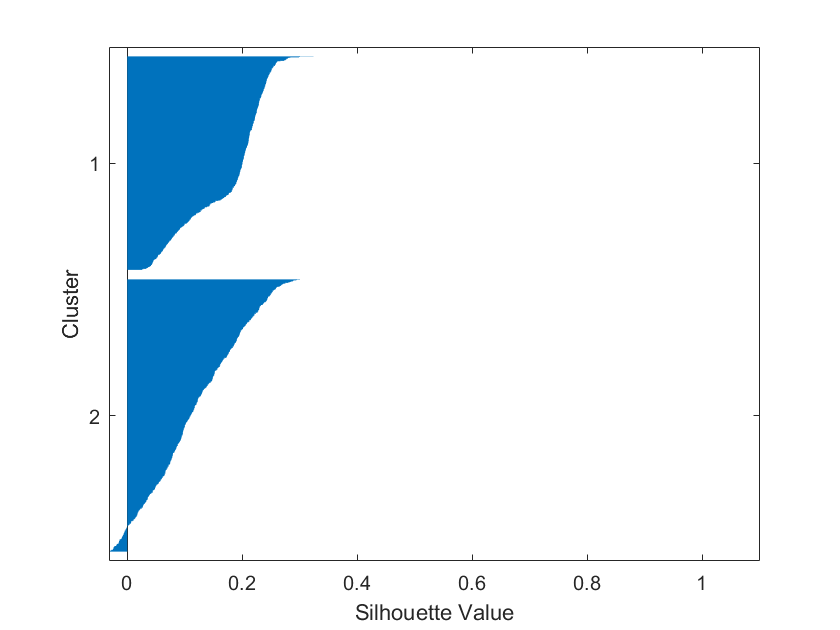


idx=kmeans(HCV_arr(:,[1,3,11:end-2]),k);
silhouette(HCV_arr(:,[1,3,11:end-2]),idx)

Can be used to classify into advanced and moderate fibrosis

%K-mediods clustering for categorical variables
k_values=2:5;
n=length(k_values);
s_score=zeros(n,1);
for i=1:n
    idx=kmedoids(HCV_arr(:,[2,4:10]),k_values(i));
    s=silhouette(HCV_arr(:,[2,4:10]),idx);
    s_score(i)=mean(s);
end
table(k_values',s_score)

ans = 4×2 table
    Var1    s_score
    ____    _______

     2      0.16331
     3      0.15183
     4      0.15298
     5      0.14836


k=find(s_score==max(s_score))+1

k = 2

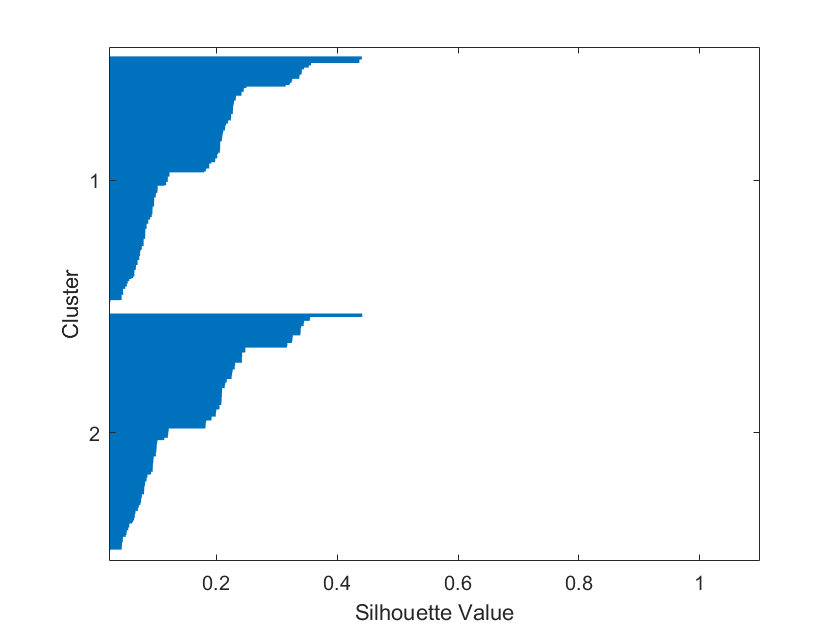


idx=kmedoids(HCV_arr(:,[2,4:10]),k);
silhouette(HCV_arr(:,[2,4:10]),idx)

# Supervised

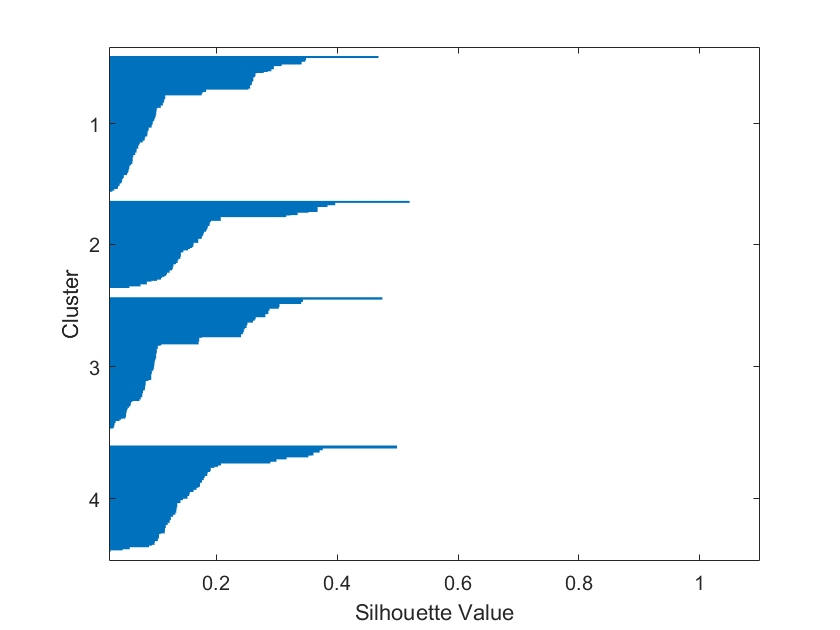

idx=kmedoids(HCV_arr(:,[2,4:10]),4,"Distance","hamming");
silhouette(HCV_arr(:,[2,4:10]),idx)

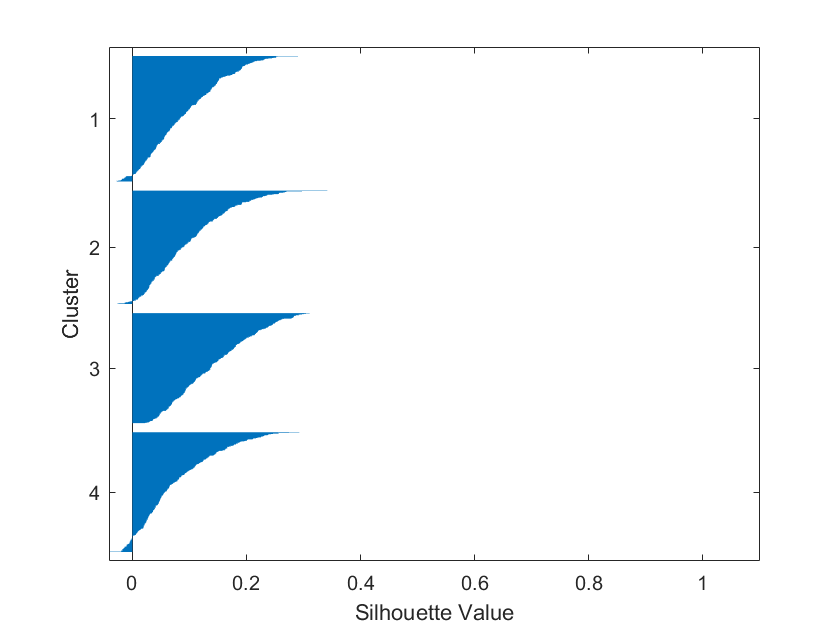

idx=kmeans(HCV_arr(:,[1,3,11:end-2]),4);
silhouette(HCV_arr(:,[1,3,11:end-2]),idx)

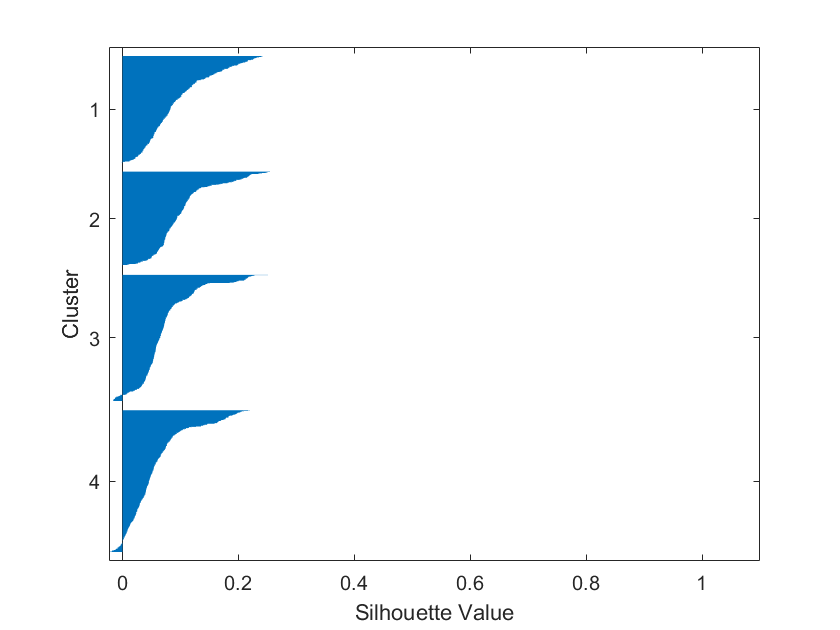

idx=kmeans(HCV_arr,4,'Distance',"sqeuclidean");
silhouette(HCV_arr,idx)

Train and Test Data

x=HCV_arr(:,1:27);
y=HCV_arr(:,29);
[Xtrain, Ytrain, Xtest, Ytest]=trainTestSplit(x,y,0.7);

### Multinomial Logistic Regression

[b1,dev1,stats1]=mnrfit(Xtrain,categorical(Ytrain))

b1 =    -0.4338    0.1025   -0.2865
   -0.0465    0.5943    0.4326
   -0.0645   -0.1050    0.1839
    0.5888    0.7952    0.4098
    0.2246   -0.0440    0.0202
   -0.1710   -0.3358   -0.0713
   -0.1749   -0.0383   -0.1960
    0.1665    0.0716    0.0118
    0.0019    0.1755   -0.0064
   -0.1752    0.3470   -0.1422


dev1 = 2.5823e+03

stats1 = struct with fields:
         beta: [28×3 double]
          dfe: 2817
         sfit: 1.0162
            s: 1
      estdisp: 0
         covb: [84×84 double]
    coeffcorr: [84×84 double]
           se: [28×3 double]
            t: [28×3 double]
            p: [28×3 double]
        resid: [967×4 double]
       residp: [967×4 double]
       residd: [967×1 double]


[val,pred1]=max(mnrval(b1,Xtest)')

val =     0.5079    0.3649    0.3030    0.3684    0.3418    0.4220    0.4388    0.3518    0.3762    0.3324    0.3467    0.4240    0.4019    0.2949    0.2936    0.3351    0.3321    0.4156    0.2849    0.3771    0.3800    0.4101    0.3004    0.2899    0.2941    0.3277    0.3386    0.3673    0.3107    0.4944    0.3356    0.2879    0.2830    0.3217    0.3362    0.3019    0.4265    0.3409    0.3295    0.2892    0.3924    0.3465    0.2862    0.4021    0.3571    0.3198    0.4075    0.3033    0.3239    0.2895


pred1 =      4     1     1     2     4     4     1     1     4     2     4     2     4     4     1     4     1     1     4     4     1     4     4     4     3     2     3     4     2     2     3     1     2     3     4     1     4     4     4     3     4     2     3     2     1     4     4     4     2     3


pred1=normalize(pred1','range')

pred1 =     1.0000
         0
         0
    0.3333
    1.0000
    1.0000
         0
         0
    1.0000
    0.3333


accuracy1=sum(pred1==Ytest)/length(Ytest)

accuracy1 = 0.2150

confusionmat(double(Ytest),double(pred1))

Class List in given sample
         0
    0.3333
    0.6667
    1.0000


Total Instance = 414
class1==>0
class2==>0.33333
class3==>0.66667
class4==>1
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          22                21                17                32      
    Actual_class2          25                22                20                33      
    Actual_class3          31                25                15                49      
    Actual_class4          27                25                20                30      

Multi-Class Confusion Matrix Output
                     TruePositive 

ans =     22    21    17    32
    25    22    20    33
    31    25    15    49
    27    25    20    30


## 5 fold cross validation

fold=5;
index1=crossvalind('kfold',size(Xtrain,1),fold);
accuracy1=zeros(1,fold);
%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain=x(train,:);
    Xtest=x(test,:);
    Ytrain=y(train,:);
    Ytest=y(test,:);
    
    %Multinomial Logistic Regression
    [b1,dev1,stats1]=mnrfit(Xtrain,categorical(Ytrain));
    [~,pred1]=max(mnrval(b1,Xtest)');
    pred1=normalize(pred1','range');
    accuracy1(i)=sum(pred1==Ytest)/length(Ytest)
    confusionmat(double(Ytest),double(pred1))
end

accuracy1 =     0.2280         0         0         0         0


Class List in given sample
         0
    0.3333
    0.6667
    1.0000


Total Instance = 193
class1==>0
class2==>0.33333
class3==>0.66667
class4==>1
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          12                11                14                11      
    Actual_class2          12                 6                16                13      
    Actual_class3          15                 8                13                13      
    Actual_class4          10                11                15                13      

Multi-Class Confusion Matrix Output
                     TruePositive 

ans =     12    11    14    11
    12     6    16    13
    15     8    13    13
    10    11    15    13


accuracy1 =     0.2280    0.2474         0         0         0


Class List in given sample
         0
    0.3333
    0.6667
    1.0000


Total Instance = 194
class1==>0
class2==>0.33333
class3==>0.66667
class4==>1
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1           8                7                 14                25      
    Actual_class2          11                8                  7                14      
    Actual_class3          15                7                 11                17      
    Actual_class4          12                8                  9                21      

Multi-Class Confusion Matrix Output
                     TruePositive 

ans =      8     7    14    25
    11     8     7    14
    15     7    11    17
    12     8     9    21


accuracy1 =     0.2280    0.2474    0.2165         0         0


Class List in given sample
         0
    0.3333
    0.6667
    1.0000


Total Instance = 194
class1==>0
class2==>0.33333
class3==>0.66667
class4==>1
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1           8                11                17                18      
    Actual_class2          11                 9                10                16      
    Actual_class3          10                13                 9                16      
    Actual_class4           9                 7                14                16      

Multi-Class Confusion Matrix Output
                     TruePositive 

ans =      8    11    17    18
    11     9    10    16
    10    13     9    16
     9     7    14    16


accuracy1 =     0.2280    0.2474    0.2165    0.2332         0


Class List in given sample
         0
    0.3333
    0.6667
    1.0000


Total Instance = 193
class1==>0
class2==>0.33333
class3==>0.66667
class4==>1
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          12                 6                13                15      
    Actual_class2          14                 6                16                 9      
    Actual_class3           8                14                10                13      
    Actual_class4          16                 7                17                17      

Multi-Class Confusion Matrix Output
                     TruePositive 

ans =     12     6    13    15
    14     6    16     9
     8    14    10    13
    16     7    17    17


accuracy1 =     0.2280    0.2474    0.2165    0.2332    0.2021


Class List in given sample
         0
    0.3333
    0.6667
    1.0000


Total Instance = 193
class1==>0
class2==>0.33333
class3==>0.66667
class4==>1
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1           7                 9                 9                18      
    Actual_class2          21                 5                 8                10      
    Actual_class3          17                10                12                16      
    Actual_class4          21                 5                10                15      

Multi-Class Confusion Matrix Output
                     TruePositive 

ans =      7     9     9    18
    21     5     8    10
    17    10    12    16
    21     5    10    15


avg_accuracy_5=mean(accuracy1)

avg_accuracy_5 = 0.2254

%Can be used for 2 stage determination
b2=fitlm(Xtrain,Ytrain)

b2 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    ________    _________    __________

    (Intercept)       0.49918     0.11087       4.5023    7.5655e-06
    x1              -0.034554     0.03984     -0.86731       0.38599
    x2              0.0098199     0.02421      0.40561       0.68512
    x3              -0.061364    0.038585      -1.5904       0.11208
    x4              -0.032563    0.024134      -1.3492       0.17759
    x5                0.03186    0.024179       1.3177      

pred2=round(predict(b2,Xtest))

p2 =      1
     1
     1
     0
     1
     1
     1
     1
     0
     1


accuracy2=sum(pred2==Ytest)/length(Ytest)

Unrecognized function or variable 'pred_lr2'.

precision2=sum(pred2==1 & Ytest==1)/sum(pred2==1)
recall2=sum(pred2==1 & Ytest==1)/sum(Ytest==1)

x1=dat(:,1:27);
y1=categorical(dat(:,29));
fold=5;
index1=crossvalind('kfold',size(Xtrain,1),fold);
accuracy5_=zeros(1,fold);
%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain=x1(train,:);
    Xtest=x1(test,:);
    Ytrain=y1(train,:);
    Ytest=y1(test,:);
    
    %Random Forest
    RFmodel=TreeBagger(100,Xtrain,Ytrain,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on");
    Ypred=predict(RFmodel,Xtest); % RF gives output in cell array format
    Ypred=categorical(Ypred); % cell array to categorical array
   
    % For model accuracy
    accuracy5_(i)=sum(Ypred==Ytest)/length(Ytest)
    confusionmat(double(Ytest),double(Ypred))
end
accuracy5_
avg_accuracy_5=mean(accuracy5_)

Lasso regression

[b2, Fit2] = lasso(Xtrain,Ytrain,'CV',5)
b2_lasso=b2(:,Fit2.IndexMinMSE)
pred2=Xtest*b2_lasso + Fit2.Intercept(Fit2.IndexMinMSE)
accuracy2=sum(pred2==Ytest)/length(Ytest)

%Stepwisefit
[b3,~,~,inmodel]=stepwisefit(Xtrain,Ytrain)
b3(~inmodel)=0
pred3=Xtest*b3
accuracy3=sum(pred3==Ytest)/length(Ytest)

### PLS Regression

[XL, YL,~,~,b4,pctvar]=plsregress(Xtrain,Ytrain,27)


% Group data by stages and apply anova
HCV_dat=array2table(HCV_array,'VariableNames',HCV.Properties.VariableNames)

HCV_dat = 1381×29 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____

HCV_dat.Gender=categorical(HCV_dat.Gender)

HCV_dat = 1381×29 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____

for i=[2,4:10,28:29]
    HCV_dat.(i)=categorical(HCV_dat.(i));
end
class(HCV_dat.Fatiguegeneralizedboneache)

ans = 'categorical'

Features\Response     Continuous    Categorical

Continuous                   Pearson's corr      LDA

Categorical                   ANOVA         Chi-Square

% FILTER TYPE FEATURE SELECTION
% Method 1 - Rank features sequentially using the Minimum Redundancy Maximum Relevance (MRMR) Algorithm.
[idx,scores] = fscmrmr(HCV_dat,'Baselinehistologicalstaging')

idx =     26    25    27     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    28


scores =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.0070    0.0121    0.0054         0


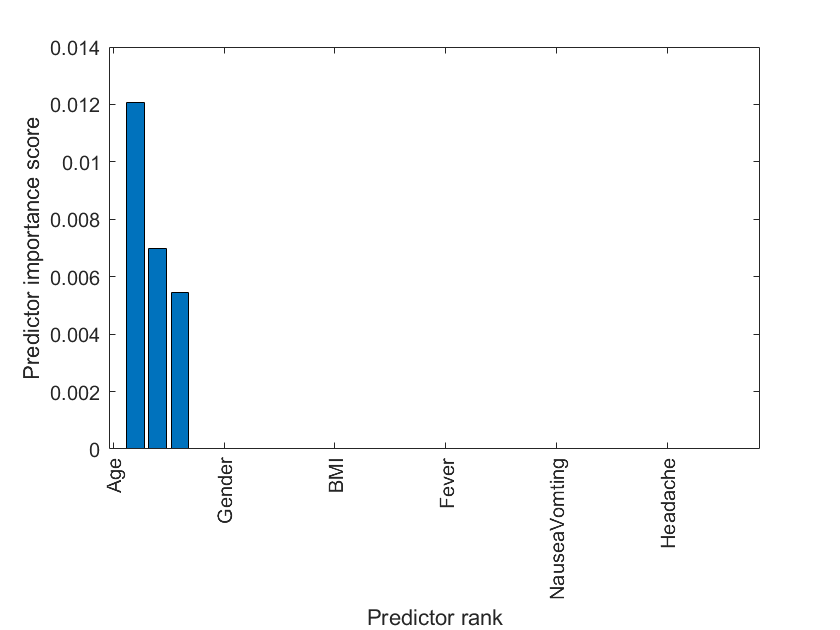

bar(scores(idx))
xlabel('Predictor rank')
ylabel('Predictor importance score')
xticklabels(HCV_dat.Properties.VariableNames(1:28))
xtickangle(90)

p=array2table(scores',"RowNames",HCV_dat.Properties.VariableNames(1:28))

p = 28×1 table
                                  Var1
                                  ____

    Age                            0  
    Gender                         0  
    BMI                            0  
    Fever                          0  
    NauseaVomting                  0  
    Headache                       0  
    Diarrhea                       0  
    Fatiguegeneralizedboneache     0  
    Jaundice                       0  
    Epigastricpain                 0  
    WBC                            0  
    RBC                            0  
    HGB                            0  
    Plat                           0  
    AST1                           0  
    ALT1                

sortrows(p,'Var1','descend')

ans = 28×1 table
                                    Var1   
                                  _________

    RNAEOT                         0.012059
    RNA12                         0.0069818
    RNAEF                         0.0054406
    Age                                   0
    Gender                                0
    BMI                                   0
    Fever                                 0
    NauseaVomting                         0
    Headache                              0
    Diarrhea                              0
    Fatiguegeneralizedboneache            0
    Jaundice                              0
    Epigastricpain                        0
    WBC                                   0
    <s

% MATLAB 2020 has fsrftest and fscchi2
% fscchi2 -> 15 10 2 24 17 5 12 27 21 13 9 3 16 22 18 4 25 1 20 8 28 7 26
% 19 14 23 6 11

% Method 2 - fscchi2
% 1st 12 greater than 1
chisq=[15 ,10 ,2 ,24, 17, 5, 12, 27, 21, 13, 9, 3, 16, 22, 18, 4, 25, 1, 20, 8, 28, 7, 26, 19, 14, 23, 6, 11]

chisq =     15    10     2    24    17     5    12    27    21    13     9     3    16    22    18     4    25     1    20     8    28     7    26    19    14    23     6    11


chisq'

ans =     15
    10
     2
    24
    17
     5
    12
    27
    21
    13


HCV_dat.Baselinehistologicalstaging=grp2idx(HCV_dat.Baselinehistologicalstaging)

HCV_dat = 1381×29 table
    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____

mdl=fitlm(HCV_dat,'interactions',"ResponseVar","Baselinehistologicalstaging",'CategoricalVars',{'BaselinehistologicalGrading','Diarrhea','Epigastricpain','Fatiguegeneralizedboneache','Fever','Gender','Headache','Jaundice','NauseaVomting'})

mdl = Linear regression model:
    Baselinehistologicalstaging ~ 1 + Age*Gender + Age*BMI + Age*Fever + Age*NauseaVomting + Age*Headache + Age*Diarrhea + Age*Fatiguegeneralizedboneache + Age*Jaundice + Age*Epigastricpain + Age*WBC + Age*RBC + Age*HGB + Age*Plat + Age*AST1 + Age*ALT1 + Age*ALT4 + Age*ALT12 + Age*ALT24 + Age*ALT36 + Age*ALT48 + Age*ALTafter24w + Age*RNABase + Age*RNA4 + Age*RNA12 + Age*RNAEOT + Age*RNAEF + Age*BaselinehistologicalGrading + Gender*BMI + Gender*Fever + Gender*NauseaVomting + Gender*Headache + Gender*Diarrhea + Gender*Fatiguegeneralizedboneache + Gender*Jaundice + Gender*Epigastricpain + Gender*WBC + Gender*RBC + Gender*HGB + Gender*Plat + Gender*AST1 + Gender*ALT1 + Gender*ALT4 + Gender*ALT12 + Gender*ALT24 + Gender*ALT36 + Gender*ALT48 + Gender*ALTafter24w + Gender*RNABase + Gender*RNA4 + Gender*RNA12 + Gender*RNAEOT + Gender*RNAEF + Gender*BaselinehistologicalGrading + BMI*Fever + BMI*NauseaVomting + BMI*Headache + BMI*Diarrhea + BMI*Fatiguegeneralizedbo

x=HCV_array(:,1:27)

x =           46           1          29           1           2           2           1           2           2           1       12101     4429425          10      129367          91         123          95          75         113          57         123          44       40620      538635      637056      336804       31085
          57           1          33           2           2           2           2           1           1           1        4178     4621191          12      151522         113          49          95         107         116           5           5           5      571148      661346           5      735945      558829
          59           1          32           1           1           2           1           2           2           2        3661     4606375          11      187684          99         104          67          48         120          94          90          30      660410      738756     3731527      338946      242861
          58         

y=HCV_array(:,29)

y =      2
     4
     1
     4
     3
     2
     2
     2
     1
     1


[Xtrain, Ytrain, Xtest, Ytest]=trainTestSplit(x,y,0.7)

Xtrain =           58           2          22           1           1           1           1           2           1           1        5315     4940743          13      183372          63          80          53          64         104          62         105          27      844758      334274      364269      182617      800950
          42           2          31           2           1           1           1           1           2           1        4330     4853740          14      116873         126          71          83          48          79          43         111          31      963179      952973      331275      547203      306884
          44           2          25           1           2           1           2           2           1           1       11256     4742632          15      149356          63         128         120          80          68         126          48          22      761864      659551      289176      455211      340102
          40    

Ytrain =      3
     4
     1
     4
     4
     4
     3
     1
     3
     1


Xtest =           57           1          33           2           2           2           2           1           1           1        4178     4621191          12      151522         113          49          95         107         116           5           5           5      571148      661346           5      735945      558829
          45           2          25           2           1           1           1           2           1           2        9279     4116937          13      203003          97         101          66          53          95          55         104          26      936444      536969           5           5           5
          57           2          23           1           1           2           2           1           1           1        5925     4031637          15      116558          86         109         118         119          55         103          84          32      169624      786017      669076      531187      282524
          51     

Ytest =      4
     1
     2
     1
     1
     1
     2
     2
     1
     1


b2=fitlm(Xtrain,Ytrain)

b_lr2 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27

Estimated Coefficients:
                    Estimate          SE         tStat        pValue  
                   ___________    __________    ________    __________

    (Intercept)         2.9656       0.79665      3.7226    0.00020889
    x1              -0.0030685     0.0040854    -0.75108       0.45279
    x2              0.00028139      0.071746    0.003922       0.99687
    x3               -0.017279     0.0087889      -1.966      0.049592
    x4                -0.13048      0.071853     -1.8159      0.069704
    x5                 0.11342      0.07194

pred2=round(predict(b2,Xtest))

pred_lr2 =      3
     3
     3
     3
     3
     3
     3
     2
     2
     2


a_lr2=sum(pred2==Ytest)/length(Ytest)

a_lr2 = 0.2271

p_lr2=sum(pred2==1 & Ytest==1)/sum(pred2==1)

p_lr2 = NaN

m_lr2=mean(abs(pred2-Ytest))

m_lr2 = 1.0483

c_lr2=corr(pred2,Ytest)

c_lr2 = 6.2321e-04

% 21,18,20,6,12,25,15,2,8
b2=fitlm(Xtrain(:,[1,3:5,7,9:11,13:14,16:17,19,22:24,26:27]),Ytrain)

b_lr2 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18

Estimated Coefficients:
                    Estimate          SE          tStat        pValue  
                   ___________    __________    _________    __________

    (Intercept)          3.105       0.58022       5.3514    1.0946e-07
    x1              -0.0030117     0.0040675     -0.74042       0.45923
    x2               -0.017508     0.0087536      -2.0001      0.045775
    x3                -0.12358      0.071265       -1.734      0.083235
    x4                 0.11459      0.071565       1.6012       0.10967
    x5               -0.080035      0.071588       -1.118       0.26385
    x6    

% Here p-val =0.0492
pred2=round(predict(b2,Xtest(:,[1,3:5,7,9:11,13:14,16:17,19,22:24,26:27])))

pred_lr2 =      3
     2
     3
     3
     3
     3
     3
     2
     2
     3


a_lr2=sum(pred2==Ytest)/length(Ytest)

a_lr2 = 0.2391

p_lr2=sum(pred2==1 & Ytest==1)/sum(pred2==1)

p_lr2 = NaN

m_lr2=mean(abs(pred2-Ytest))

m_lr2 = 1.0242

c_lr2=corr(pred2,Ytest)

c_lr2 = 0.0418

% fitlm and add and remove using step
mdl1=fitlm(HCV_dat(:,[1:27,29]),'ResponseVar','Baselinehistologicalstaging','CategoricalVars',{'Diarrhea','Epigastricpain','Fatiguegeneralizedboneache','Fever','Gender','Headache','Jaundice','NauseaVomting'})

mdl1 = Linear regression model:
    Baselinehistologicalstaging ~ 1 + Age + Gender + BMI + Fever + NauseaVomting + Headache + Diarrhea + Fatiguegeneralizedboneache + Jaundice + Epigastricpain + WBC + RBC + HGB + Plat + AST1 + ALT1 + ALT4 + ALT12 + ALT24 + ALT36 + ALT48 + ALTafter24w + RNABase + RNA4 + RNA12 + RNAEOT + RNAEF

Estimated Coefficients:
                                     Estimate          SE         tStat        pValue  
                                    ___________    __________    ________    __________

    (Intercept)                          2.9996       0.63067      4.7563    2.1831e-06
    Age                              -0.0028401     0.0034545    -0.82214       0.41114
    Gender_2                           0.027253      0.060774     0.44843       0.65392
    BMI      

newmdl1=step(mdl1)

1. Adding ALT12:RNA12, FStat = 7.7034, pValue = 0.0055876


newmdl1 = Linear regression model:
    Baselinehistologicalstaging ~ 1 + Age + Gender + BMI + Fever + NauseaVomting + Headache + Diarrhea + Fatiguegeneralizedboneache + Jaundice + Epigastricpain + WBC + RBC + HGB + Plat + AST1 + ALT1 + ALT4 + ALT24 + ALT36 + ALT48 + ALTafter24w + RNABase + RNA4 + RNAEOT + RNAEF + ALT12*RNA12

Estimated Coefficients:
                                     Estimate          SE         tStat        pValue  
                                    ___________    __________    ________    __________

    (Intercept)                          3.3145       0.63925      5.1849    2.4904e-07
    Age                              -0.0027022     0.0034464    -0.78407       0.43313
    Gender_2                           0.031455      0.060643      0.5187       0.60406
    BMI     

newmdl2=step(mdl1,'PRemove',0.05,'PEnter',0.01)

1. Adding ALT12:RNA12, FStat = 7.7034, pValue = 0.0055876


newmdl2 = Linear regression model:
    Baselinehistologicalstaging ~ 1 + Age + Gender + BMI + Fever + NauseaVomting + Headache + Diarrhea + Fatiguegeneralizedboneache + Jaundice + Epigastricpain + WBC + RBC + HGB + Plat + AST1 + ALT1 + ALT4 + ALT24 + ALT36 + ALT48 + ALTafter24w + RNABase + RNA4 + RNAEOT + RNAEF + ALT12*RNA12

Estimated Coefficients:
                                     Estimate          SE         tStat        pValue  
                                    ___________    __________    ________    __________

    (Intercept)                          3.3145       0.63925      5.1849    2.4904e-07
    Age                              -0.0027022     0.0034464    -0.78407       0.43313
    Gender_2                           0.031455      0.060643      0.5187       0.60406
    BMI     

newmdl3=step(mdl1,'NSteps',5)

1. Adding ALT12:RNA12, FStat = 7.7034, pValue = 0.0055876
2. Adding ALT36:RNAEF, FStat = 6.5787, pValue = 0.010428
3. Adding Headache:ALT12, FStat = 5.917, pValue = 0.015125
4. Adding AST1:ALT48, FStat = 5.613, pValue = 0.017968
5. Adding Epigastricpain:HGB, FStat = 5.2925, pValue = 0.02157


newmdl3 = Linear regression model:
    Baselinehistologicalstaging ~ 1 + Age + Gender + BMI + Fever + NauseaVomting + Diarrhea + Fatiguegeneralizedboneache + Jaundice + WBC + RBC + Plat + ALT1 + ALT4 + ALT24 + ALTafter24w + RNABase + RNA4 + RNAEOT + Headache*ALT12 + Epigastricpain*HGB + AST1*ALT48 + ALT12*RNA12 + ALT36*RNAEF

Estimated Coefficients:
                                     Estimate          SE         tStat       pValue  
                                    ___________    __________    ________    _________

    (Intercept)                          2.0361       0.74755      2.7237    0.0065385
    Age                              -0.0030054      0.003429    -0.87645      0.38094
    Gender_2                           0.034674      0.060255     0.57545      0.56508
    BMI          

b2=fitlm(Xtrain(:,[18:25]),Ytrain)

Error using classreg.regr.FitObject/selectVariables (line 342)
Response variable must be a numeric vector.

Error in classreg.regr.TermsRegression/selectVariables (line 259)
            model = selectVariables@classreg.regr.ParametricRegression(model);

Error in <

pred2=round(predict(b2,Xtest(:,[18:25])))
a_lr2=sum(pred2==Ytest)/length(Ytest)
p_lr2=sum(pred2==1 & Ytest==1)/sum(pred2==1)
m_lr2=mean(abs(pred2-Ytest))
c_lr2=corr(pred2,Ytest)

% Accuracy = 22.71

mdls=stepwiselm(HCV_dat)

1. Adding BMI, FStat = 4.4084, pValue = 0.035943
2. Adding NauseaVomting, FStat = 4.2447, pValue = 0.03956


mdls = Linear regression model:
    Baselinehistologicalstaging ~ 1 + BMI + NauseaVomting

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                       _________    _________    _______    __________

    (Intercept)           2.9205      0.21555     13.549    2.3544e-39
    BMI                -0.015631    0.0073928    -2.1144      0.034664
    NauseaVomting_2      0.12412     0.060245     2.0603       0.03956


Number of observations: 1381, Error degrees of freedom: 1378
Root Mean Squared Error: 1.12
R-squared: 0.00625,  Adjusted R-Squared: 0.00481
F-statistic vs. constant model: 4.33, p-value = 0.0133

1. Adding BMI, FStat = 4.4084, pValue = 0.035943
2. Adding NauseaVomting, FStat = 4.2447, pValue = 0.03956


mdls1 = Linear regression model:
    Baselinehistologicalstaging ~ 1 + BMI + NauseaVomting

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                       _________    _________    _______    __________

    (Intercept)           2.9205      0.21555     13.549    2.3544e-39
    BMI                -0.015631    0.0073928    -2.1144      0.034664
    NauseaVomting_2      0.12412     0.060245     2.0603       0.03956


Number of observations: 1381, Error degrees of freedom: 1378
Root Mean Squared Error: 1.12
R-squared: 0.00625,  Adjusted R-Squared: 0.00481
F-statistic vs. constant model: 4.33, p-value = 0.0133

mdls1=stepwiselm(Xtrain,Ytrain,"NSteps",20)

1. Adding x5, FStat = 7.9478, pValue = 0.004913
2. Adding x3, FStat = 4.917, pValue = 0.026827


mdls1 = Linear regression model:
    y ~ 1 + x3 + x5

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)       2.7813      0.27927      9.959    2.6364e-22
    x3             -0.019662    0.0088669    -2.2174      0.026827
    x5               0.20102     0.071924     2.7949     0.0052939


Number of observations: 967, Error degrees of freedom: 964
Root Mean Squared Error: 1.12
R-squared: 0.0132,  Adjusted R-Squared: 0.0112
F-statistic vs. constant model: 6.45, p-value = 0.00165

pred_s=round(predict(mdls1,Xtest))

pred_s =      3
     2
     3
     2
     2
     2
     3
     2
     3
     3


[pred_s Ytest]

ans =      3     4
     2     1
     3     2
     2     1
     2     1
     2     1
     3     2
     2     2
     3     1
     3     1


a_s=sum(pred_s==Ytest)/length(Ytest)

a_s = 0.2633

p_s=sum(pred_s==1 & Ytest==1)/sum(pred_s==1)

p_s = NaN

m_s=mean(abs(pred_s-Ytest))

m_s = 0.9855

c_s=corr(pred_s,Ytest)

c_s = 0.0059

% Exclusion Criterion
sum(HCV_dat.Age<=18)

ans = 0

sum(HCV_dat.Age>=65)

ans = 0

sum(HCV_dat.BMI>35)

ans = 0


%The Kruskal-Wallis test has been used for continuous variables with nonnormal distribution. 
%The chi-square test has been used for categorical variables. 
%Pearson's correlation coefficients between fibrosis and each variable have been
%assessed.
%F0 and F1 were considered as mild fibrosis and F2 as moderate, whereas F3-F4 were considered as advanced fibrosis 